close("all"); clear; clc;

time = optvar("time","t","time","s",0);
position = optvar("position","x","position","m",0,1);
velocity = optvar("velocity","v","speed","m/s",0,0);

states = [
    position;
    velocity
    ];

force = optvar("force","F","force","N",[],[],-1,1);
controls = force;

x = ocpvars(time,states,controls);

w = ocpcost(x,@(x,u)1 + 0.*u(1,:));

plant = dyncon(x,@(x,u)slidingMass(x,u,1));

C = ocpcon(x,plant);

prob = ocp(x,w,C);
disp(prob)

============================ Optimal Control Problem ===========================
                                    MINIMISE                                    


$$J=t_{f}$$

                                   SUBJECT TO                                   
=================================== Dynamics ===================================


$$\frac{\partial }{\partial t}x\left(t\right)=v\left(t\right)$$

$$\frac{\partial }{\partial t}v\left(t\right)=F\left(t\right)$$

============================== Control path bounds =============================


$$-1\leq F\left(t\right)$$

$$F\left(t\right)\leq 1$$

ns = 10;
M = ns + 1;

x0 = zeros(2,M);
u0 = zeros(1,M);
y0 = [x0;u0];
z0 = [1;y0(:)];
prog = transcribe(@Trapezoidal,prob,z0);

opts = optimoptions( ...
    "fmincon", ...
    "MaxFunctionEvaluations",1E06, ...
    "MaxIterations",1E04 ...
    );
prog.solve(opts);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


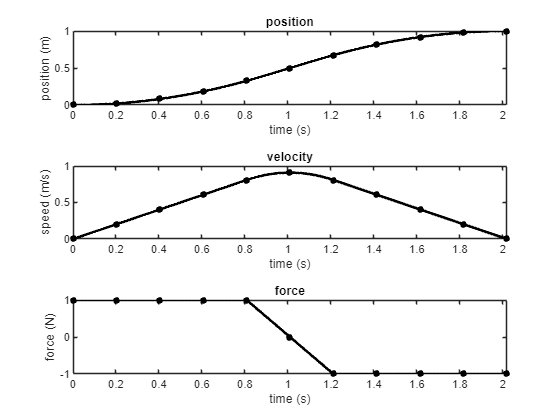

fig = prog.plot(3,1);